% 
v = load('t2_cmos.sfit', '-mat');
my_model = v.savedSession.AllFitdevsAndConfigs{1, 1}.Fitdev.Fit

my_model =      General model:
     my_model(x) = a*exp(-b*x)+c
     Coefficients (with 95% confidence bounds):
       a =      0.1646  (0.1005, 0.2287)
       b =       1.938  (0.7854, 3.09)
       c =      0.8819  (0.8677, 0.8961)

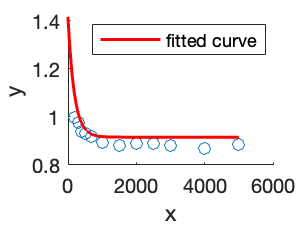

filename = 'lasonde_t1_measurements_cmos.xlsx'; 

data = readtable(filename, 'VariableNamingRule', 'preserve');
time_axis = (data.Time(2:end));
photon_num_axis = (data.V(2:end));
deviation = (data.dev(2:end));

ci = predint(my_model, x);
figure()
hold on;
scatter(time_axis, photon_num_axis,LineWidth=0.2);
h = plot(my_model, 'r');
h.LineWidth = 1.5;

plot(time_axis, ci, '--', LineWidth=1.5);

Error using plot
Vectors must be the same length.

errorbar(time_axis, photon_num_axis, deviation, 'k');
hold off;
grid;
legend('Raw data points', 'Line of best fit', 'Lower 95% CI', 'Upper 95% CI')
title("Time delay (us) vs. Outputted voltage from photodiode (V) for T_2 decay");
xlabel('Time delay (us)') ;
ylabel('Outputted voltage from photodiode (V)');

